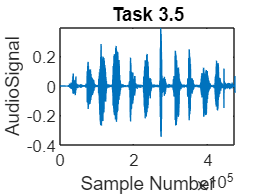

%3.1 Read sample in
[data, sampleRate] = audioread("Sound clips\AzBio_Male_Words.wav");

%3.2 If stereo, make mono
sizeVar = size(data);
if sizeVar(1,2) == 2
    dataMono = sum(data,2);
    data = dataMono;
end

%3.3 Play sound
sound(data, sampleRate)

%3.5 Plot data
n = 1:sizeVar(1,1);
plot(n, data)
xlabel('Sample Number');
ylabel('AudioSignal');
title('Task 3.5')

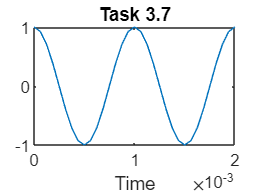


%3.6 Resample to 16kHz
if sampleRate > 16000
    dataResampled = resample(data, 16000, sampleRate);
end

if sampleRate < 16000
    disp("Get a new file with a sampling rate at least 16 kHz")
end

sizeVar = size(dataResampled);
data = dataResampled;

%3.7 Produce a sound with 1kHz frequency
%t = 1/16000:1/16000:sizeVar(1,1)/sampleRate; %0 < t < sampleLength
%y = cos(1000*2*pi*t);
%sound(y,16000)

%Plot 2 periods of a 1kHz cosine function
t2 = 0:1/16000:2/1000;
y2 = cos(2000*pi*t2);
plot(t2,y2)
xlabel("Time");
title("Task 3.7")

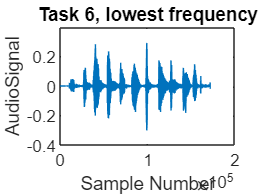


%Phase 2
%Task 4 and 5
Fstop1 = 99;        % First Stopband Frequency
Fpass1 = 100;        % First Passband Frequency
Fpass2 = 758;        % Second Passband Frequency
Fstop2 = 759;        % Second Stopband Frequency

arrayFilteredData = [];
arrayCenterFrequencies = [];
for i = 1:12
    Fs = 16000;  % Sampling Frequency
    Astop1 = 75;      % First Stopband Attenuation (dB)
    Apass  = 0.01;    % Passband Ripple (dB)
    Astop2 = 75;      % Second Stopband Attenuation (dB)
    match  = 'both';  % Band to match exactly

    % Construct an FDESIGN object and call its ELLIP method.
    h  = fdesign.bandpass(Fstop1, Fpass1, Fpass2, Fstop2, Astop1, Apass, ...
                      Astop2, Fs);
    Hd = design(h, 'ellip', 'MatchExactly', match);
    filtered_signal = filter(Hd,data);
   
    arrayCenterFrequencies = horzcat(arrayCenterFrequencies, sqrt(Fpass1*Fpass2));

    %sound(filtered_signal, sampleRate)
    if i == 11
        Fstop1 = Fstop1 + 658;
        Fpass1 = Fpass1 + 658;
        Fstop2 = Fstop2 + 661;
        Fpass2 = Fpass2 + 661;
    else
        Fstop1 = Fstop1 + 658;
        Fpass1 = Fpass1 + 658;
        Fstop2 = Fstop2 + 658;
        Fpass2 = Fpass2 + 658;
    end

    arrayFilteredData = horzcat(arrayFilteredData, filtered_signal);
end

%Task 6
n = 1:sizeVar(1,1);
plot(n, arrayFilteredData(:,1))
xlabel('Sample Number');
ylabel('AudioSignal');
title('Task 6, lowest frequency')

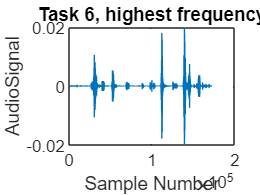


n = 1:sizeVar(1,1);
plot(n, arrayFilteredData(:,12))
xlabel('Sample Number');
ylabel('AudioSignal');
title('Task 6, highest frequency')

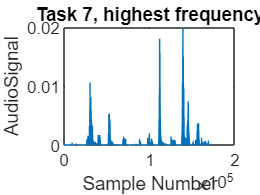


%Task 7
arrayAbsoluteSignals = [];
for i = 1:12
    arrayAbsoluteSignals = horzcat(arrayAbsoluteSignals, abs(arrayFilteredData(:,i)));
end


n = 1:sizeVar(1,1);
plot(n, arrayAbsoluteSignals(:,12))
xlabel('Sample Number');
ylabel('AudioSignal');
title('Task 7, highest frequency')

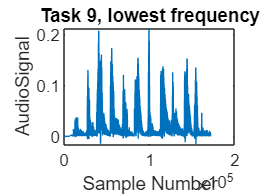


%Task 8
Fs = 16000;  % Sampling Frequency

Fpass = 400;             % Passband Frequency
Fstop = 500;             % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 0.0001;          % Stopband Attenuation
dens  = 20;              % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fpass, Fstop]/(Fs/2), [1 0], [Dpass, Dstop]);

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd = dfilt.dffir(b);

arrayEnvelopedSignals = [];
for i = 1:12
    enveloped_signal = filter(Hd, arrayAbsoluteSignals(:,i));
    arrayEnvelopedSignals = horzcat(arrayEnvelopedSignals, enveloped_signal);
end

n = 1:sizeVar(1,1);
plot(n, arrayEnvelopedSignals(:,1))
xlabel('Sample Number');
ylabel('AudioSignal');
title('Task 9, lowest frequency')

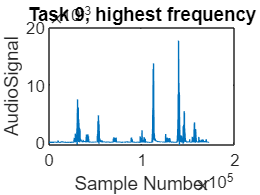


n = 1:sizeVar(1,1);
plot(n, arrayEnvelopedSignals(:,12))
xlabel('Sample Number');
ylabel('AudioSignal');
title('Task 9, highest frequency')


%Task 10
arrayCosines = [];
for i = 1:12
    centerFrequency = arrayCenterFrequencies(i);
    t = 1:1:sizeVar(1,1); %0 < t < sampleLength
    y = cos(centerFrequency*2*pi*t/16000);
    y = transpose(y);
    arrayCosines = horzcat(arrayCosines, y);
end

%Task 11
arrayAmpModCos = arrayEnvelopedSignals.*arrayCosines;

%Task 12
sumSignals = sum(arrayAmpModCos,2)

sumSignals =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


maxValue = max(abs(sumSignals))

maxValue = 0.2392

sumSignals = sumSignals/maxValue

sumSignals =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



%Task 13
sound(sumSignals, 16000)

%Write to new sample
audiowrite('New Filtered Sound clips\new_AzBio_Male3_Words.wav', sumSignals, 16000);